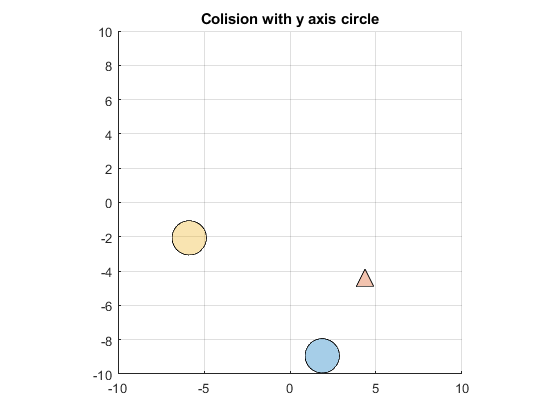

close all
c = circle;
p1 = polyshape(circle.xdata,circle.ydata);
p2 = polyshape(triangle.xdata,triangle.ydata);
p3 = polyshape(circle.xdata,circle.ydata);
x = [1 0];
y = [0 1];
trans = zeros(3,2);
[v1,b1,v2,b2,v3,b3] = generateRandomV(3);
for i = linspace(0,3,50)
    f1 = translate(p1,v1*i+b1);
    f2 = translate(p2,v2*i+b2);
    f3 = translate(p3,v3*i+b3);
    % deteccion de colisiones para el triangulo usando el SAT
    for j =1:3
        trans(j,:) = [dot(x,f2.Vertices(j,:)), dot(y,f2.Vertices(j,:))];
    end
    p1min = min(trans);
    p1max = max(trans);
    if p1min(1,1) <= -10 || p1max(1,1) >= 10
        title('Collision with x axis triangle')
        break
    elseif p1min(1,2) <= -10 || p1max(1,2) >= 10
        title('Colision with y axis triangle')
        break
    end
    % deteccion de clisiones para los circulos
    [cx1,cy1] = centroid(f1);
    [cx2,cy2] = centroid(f3);
    if cx1+c.r >= 10 || cx1-c.r <= -10 || cx2+c.r >=10 ||  cx2-c.r <=-10
        title('Colision with x axis circle')
        break
    elseif cy1+c.r > 10 || cy1-c.r <-10 || cy2+c.r >=10 ||  cy2-c.r <=-10
        title('Colision with y axis circle')
        break
    end
    renderer([f1,f2,f3])
end

v1 =      7    -5


b1 =      9    -3


v2 =     -6    -5


b2 =      2    -1


v3 =     -3     7


b3 =      2     1
